# 11. Cell Arrays

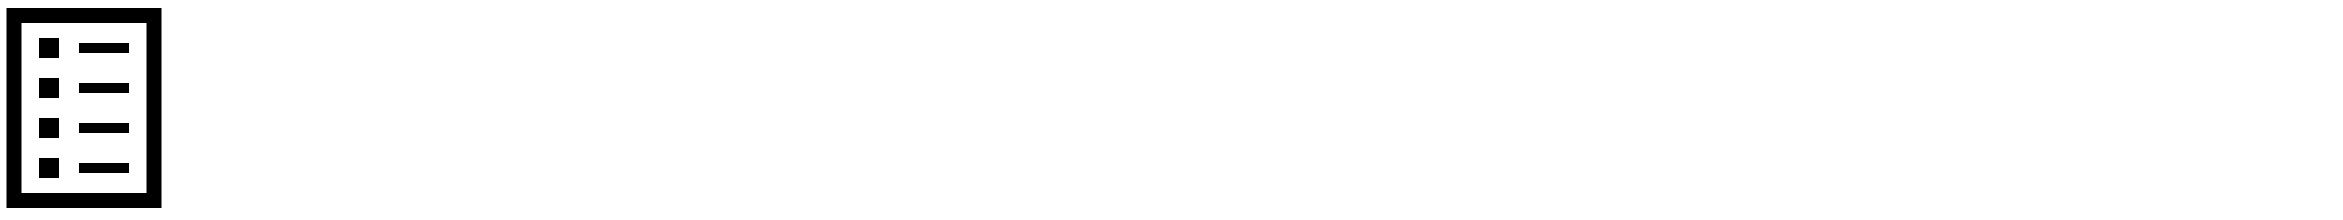

Cell arrays are like regular arrays but you can use them to store different data types in a sequence.

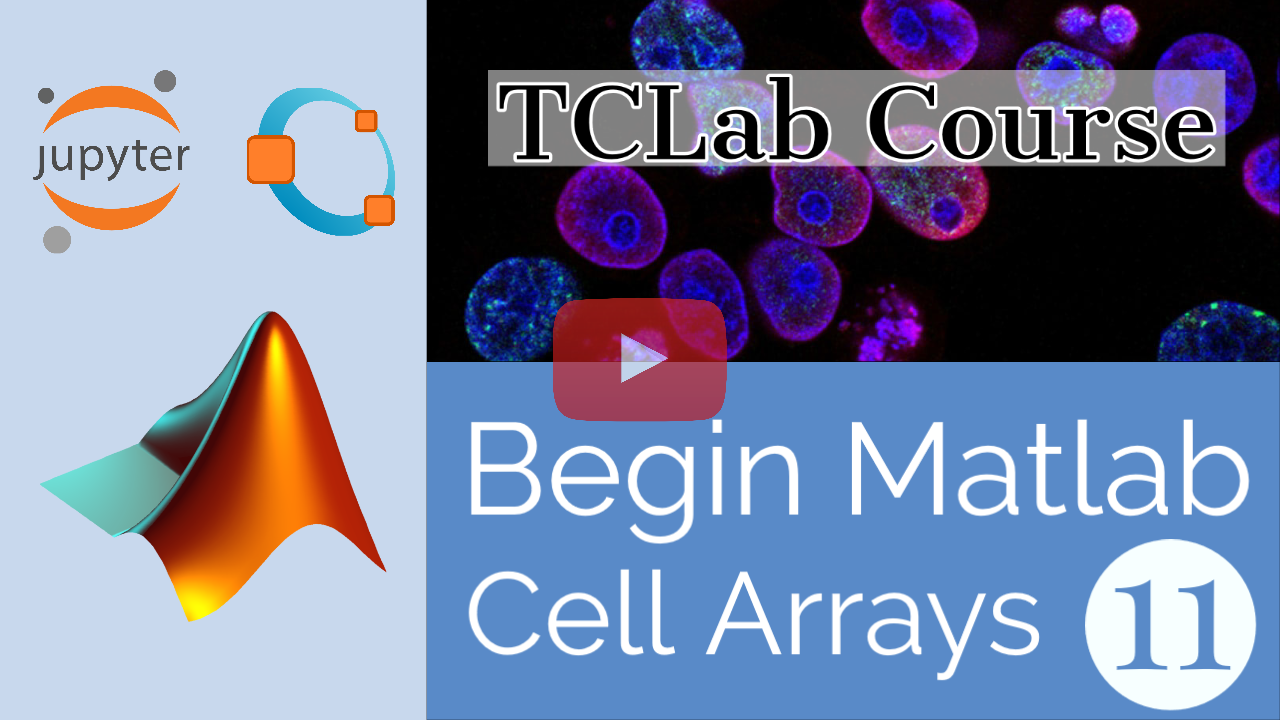

[Click here to watch the video.](https://www.youtube.com/watch?v=5nF6HutqoTQ&list=PLLBUgWXdTBDhJJnJW2q2G7e84MZM6dxRN)

The format for this method of storing values is curly brackets `{}`. After you assign the cell array a name, you can enter values and separate them with commas.

% cell array of stringschickens = {'Leghorn', 'Barnevelder', 'Plymouth Rock'}

You can also have an array in a cell array.

chickens = {'Leghorn', [true, 42],'Barnevelder', "Plymouth Rock"}

You can replace elements of the array or delete a specific value. Use `cellstr()` in Matlab to convert a string to a cell entry (optional for Octave).

chickens = {'Leghorn', 'Barnevelder', 'Plymouth Rock'}
chickens(1) = cellstr('Ancona')        % Replaces Leghorn with Ancona
chickens(2) = []                       % Deletes the second value

You can also insert a value like `'maybe'` into a cell array.

myArray = {'yes', 'no'}
myArray(3) = {'maybe'}

Use the `cell2mat()` function to convert the cell array to a matrix. An array is a 1D matrix.

chickens = {'Leghorn', 'Barnevelder', 'Plymouth Rock'};
for i = 1:length(chickens)    
    disp(cell2mat(chickens(i)))
end

Like arrays, you can access the elements of an array inside a `for` loop. The `if` statement inside controls what message is printed. The `strcmp()` function is comparing two string values. If they are the same it will be `true`.

chickens = {'Leghorn', 'Barnevelder', 'Plymouth Rock'};
disp(chickens)
for i = 1:length(chickens)    
    chicken = cell2mat(chickens(i));    
    if strcmp(chicken,'Leghorn')        
        disp('Replace with Ancona')        
        chickens(i) = cellstr('Ancona');    
    end
end
disp(chickens)

## **Activity**

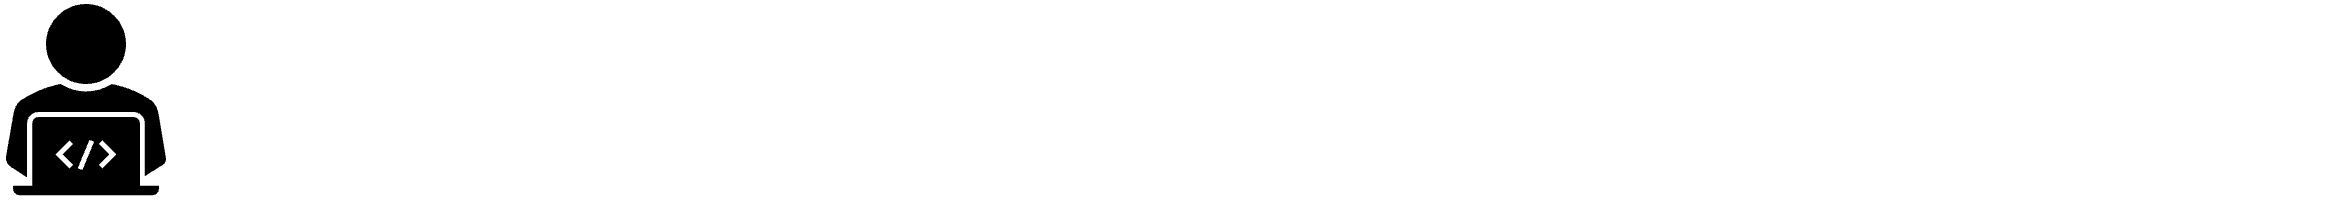

Create a cell array of animals that lay eggs (at least three).

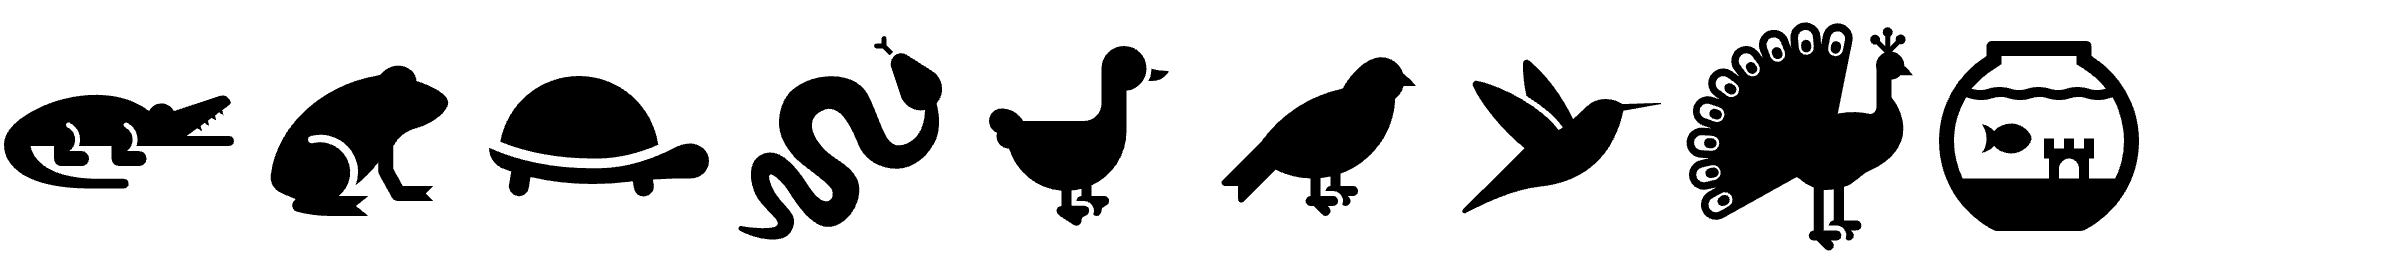

Make a while loop with an input to ask for the color of the animal and store it in a cell array. The `while` loop should stop if equal to `"none"`. Make sure the loop displays the animal and the corresponding color.

animals = {}

Turn on TCLab heater 1 `lab.Q1(70)` to 70% and record the time `datestr(clock())` and temperature `lab.T1` every second for 20 seconds for a total of 20 rows. Put the data into a cell array with the first column as the datetime and the second column as the temperature data. Save the results to a CSV file with headers `Time` and `Temperature`.

Tips for Matlab:

- Use `cellstr()` to convert the `datestr(clock())` to a cell string. You can use either `datestr(clock())` or `cellstr{datestr(clock())}` in Octave.

- Use `{lab.T1}` to convert the double precision number to a cell entry. You can use either `lab.T1` or `{lab.T1}` in Octave.